# **LAB SESSION 12**

## **Corelation.**

**Objective:** To get familiar with Corelation and its iplementation in MATLAB

**Introduction:**

    **Corelation:**

    It is a statistical technique that can show whether and hw strongly pairs of variables are related.

    There are two types of Corelation;

- +ve Corelation

- -ve Corelation


$${\mathrm{CR}}_{\mathrm{XY}} =\frac{\sum \left(X-\mathrm{X'}\right)\left(Y-\mathrm{Y'}\right)}{\sqrt{\sum {\left(X-\mathrm{X'}\right)}^2 \sum {\left(Y-\mathrm{Y'}\right)}^2 }}$$


%%Corelation
clear all
clc
N = input('Enter the Number of Samples:\n     1.Scalar (e.g: 2)\n');
for i = 1:N
    %display('For Sample #',num2str(i))
    IP = input('\nEnter the Sample Data:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n');
    n = length(IP);
    M_IP(i) = sum(IP)/n;
    
    for j = 1:n
        V(i,j) = IP(j) - M_IP(i);
    end
    
end
    SV = V.^2;
    SVX = sum(SV(1,:));
    SVY = sum(SV(2,:));
    P_SV = SVX*SVY;
for k = 1:n
    P(k) = V(1,k) * V(2,k);
end
sum_P = sum(P);

CR = sum_P/sqrt(P_SV)

CR = 0.9438


if     CR >= 0 && CR <=0.3
    disp('Weak & +ve Relation')
    
elseif CR >= 0 && CR <= 0.7
    disp('Good & +ve Relation')
    
elseif CR >= 0.7 && CR <= 1
    disp('Excellent & +ve Relation')
    
elseif CR > -0.3 && CR <= 0
    disp('Weak & -ve Relation')
    
elseif CR > -0.7 && CR <= -0.3
    disp('Good & -ve Relation')
    
elseif (CR >= -1 && CR <= -0.7)
    disp('Excellent & -ve Relation')
    
end

Excellent & +ve Relation


**TASK # 1**

**Find the Correlation and tell the type of correlation.**

**Cigrattes (X) = 0 , 5 , 10 , 15**

**Lung Capacity (Y) = 45 , 42 , 33, 31**

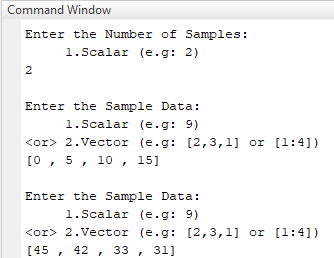

Results:

        CR = -0.9681

        `Excellent & -ve Relation`

**TASK # 2**

**Rising Hill anufacturing wishes to study the relationship between the # of Workers (X) and the # of Tables (Y). To do so 10 samples are obtained. Find the Correlation and tell the type of correlation.**

**X = 12 , 30 , 15 , 24 , 14 , 18 , 28 , 26 , 19 , 27**

**Y = 20 , 60 , 27, 50 , 21 , 30 , 61 , 54 , 32 , 57**

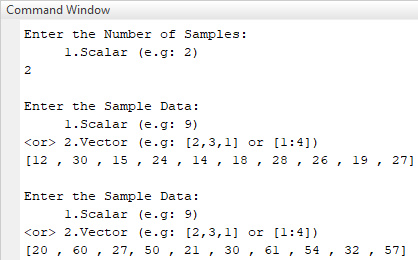

Results:

        CR = 0.9888

        `Excellent & +ve Relation`

**TASK # 3**

**Following tavle give the Weight (X) and Waist Size (Y) of 10 friends. Find the Correlation and tell the type of correlation.**

**Weight_kg (X) = 87 , 65 , 52 , 94 , 87 , 79 , 59 , 64 , 45 , 77**

**WaistSize_cm (Y) = 101 , 71 , 62 , 113 , 88 , 87 , 71 , 83 , 58 , 85**

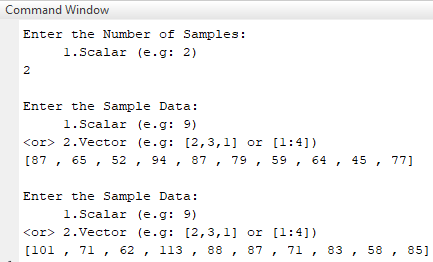

Results:

        CR = 0.9438

        `Excellent & +ve Relation`